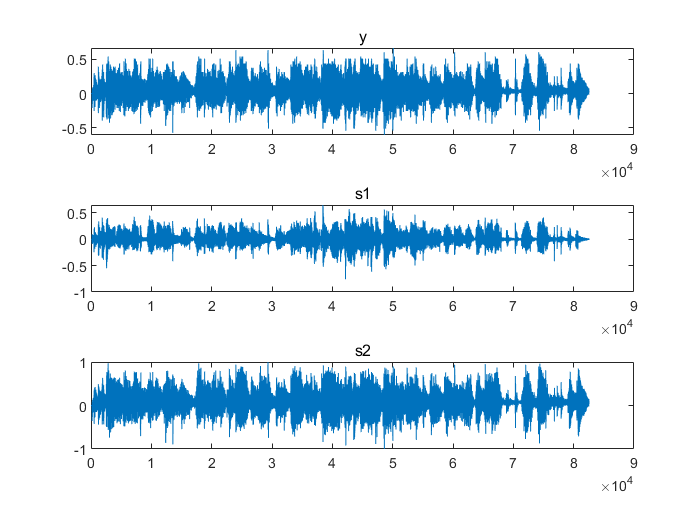


clc;
clear;
close all;
[y,Fs]=audioread("music.au");
y=y';
%sound(y,Fs);

s1=f2_6(y);
%sound(s1,Fs);

s2=f2_7(y);
%sound(s2,Fs);




figure;
subplot(3, 1, 1);
plot(y);
title('y');
subplot(3, 1, 2);
plot(s1);
title('s1');
subplot(3, 1, 3);
plot(s2);
title('s2');



N = length(y); 
Y = abs(fft(y));
S1 = abs(fft(s1));
S2 = abs(fft(s2));
f = Fs;

figure;
subplot(3, 1, 1);
plot(f, Y);
title('原始声音信号y的频谱');
subplot(3, 1, 2);
plot(f, S1);
title('序列s1的频谱');
subplot(3, 1, 3);
plot(f, S2);
title('序列s2的频谱');

% 计算频谱差异
diff_s1 = norm(Y - S1);
diff_s2 = norm(Y - S2);

disp(['s1与y的频谱差异：', num2str(diff_s1)]);
disp(['s2与y的频谱差异：', num2str(diff_s2)]);
